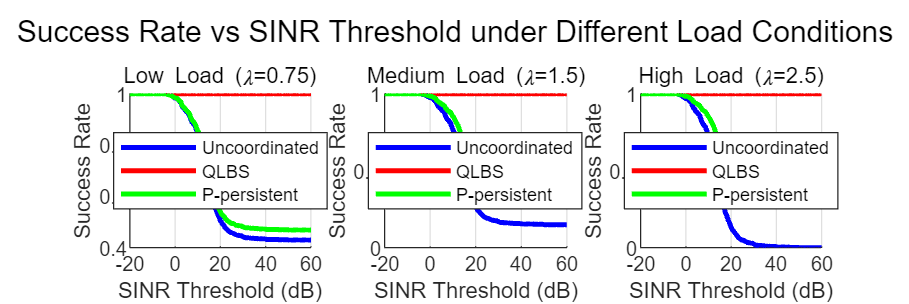


% Define the position of UE and BS
bs1_pos = [0, 0];   
bs2_pos = [1200, 0];   
radius = 700;           
numUsersPerSlot = 500; 
ue1_pos = zeros(numUsersPerSlot, 2); 
numSlots = 1000;       
maxdatarate = 2;       
lambda = [0.75, 1.5, 2.5]; 
packet_size_bits = 12000; 
slot_duration = 1;         

% 计算SINR的方法
P_tx1 = 30;  % transimission power of BS1
P_tx2 = 30;  
P_s = 0;     
P_i = 0;     
d0 = 1;      
alpha = 3;   
N0 = 1e-21;  
B = 10e6;    

% calculate power
calc_power = @(dist, PL0, exp, d0) 10^((PL0 + 10 * exp * log10(d0 / dist)) / 10);

% Define 3 methods and loads
methods = {'Uncoordinated', 'QLBS', 'P-persistent'};
SINR_thresholds = -20:0.5:60;

success_rate_all_loads = zeros(length(SINR_thresholds), 3, 3);
success_rate_vs_SINR = zeros(length(SINR_thresholds), 3, 3);


throughput_vs_SINR = zeros(length(SINR_thresholds), 3, 3);


for i = 1:numUsersPerSlot
   r1 = sqrt(rand()) * radius;    
   theta1 = rand() * 2 * pi;      
   ue1_pos(i, :) = [bs1_pos(1) + r1 * cos(theta1), bs1_pos(2) + r1 * sin(theta1)];
end


for loadIdx = 1:length(lambda)
    arrivalRate = lambda(loadIdx);

    % P-persistent 
    if(loadIdx == 1)
        p_persistent = 0.9;
    elseif(loadIdx == 2)
        p_persistent = 0.55;
    else
        p_persistent = 0.55;
    end


    queueBS1 = poissrnd(arrivalRate, 1, numSlots);
    queueBS2 = poissrnd(arrivalRate, 1, numSlots);


    activeSlots = zeros(1, 3);

    for method = 1:3

        success_rate_vs_SINR(:, method, loadIdx) = zeros(length(SINR_thresholds), 1);


        queue1 = cumsum(queueBS1);
        queue2 = cumsum(queueBS2);


        transmitBS1 = zeros(1, numSlots);
        transmitBS2 = zeros(1, numSlots);

        for t = 1:numSlots

            if method == 1 % Uncoordinated
                if queue1(t) >= maxdatarate && queue2(t) >= maxdatarate
                    transmitBS1(t) = maxdatarate;
                    transmitBS2(t) = maxdatarate;
                elseif queue1(t) >= maxdatarate
                    transmitBS1(t) = maxdatarate;
                    transmitBS2(t) = queue2(t);
                elseif queue2(t) >= maxdatarate
                    transmitBS1(t) = queue1(t);
                    transmitBS2(t) = maxdatarate;
                else
                    transmitBS1(t) = queue1(t);
                    transmitBS2(t) = queue2(t);
                end

            elseif method == 2 % QLBS
                if queue1(t) > 0 && queue2(t) > 0
                    if queue1(t) > queue2(t)
                        transmitBS1(t) = min(queue1(t), maxdatarate);
                        transmitBS2(t) = 0;
                    elseif queue1(t) < queue2(t)
                        transmitBS2(t) = min(queue2(t), maxdatarate);
                        transmitBS1(t) = 0;
                    else
                        if rand > 0.5
                            transmitBS1(t) = min(queue1(t), maxdatarate);
                            transmitBS2(t) = 0;
                        else
                            transmitBS2(t) = min(queue2(t), maxdatarate);
                            transmitBS1(t) = 0;
                        end
                    end
                else
                    if queue1(t) > 0 && queue2(t) == 0
                        transmitBS1(t) = min(queue1(t), maxdatarate);
                        transmitBS2(t) = 0;
                    elseif queue1(t) == 0 && queue2(t) > 0
                        transmitBS2(t) = min(queue2(t), maxdatarate);
                        transmitBS1(t) = 0;
                    else
                        transmitBS1(t) = 0;
                        transmitBS2(t) = 0;
                    end
                end

            elseif method == 3 % P-persistent
                if rand > p_persistent
                    transmitBS1(t) = 0; 
                else 
                    if queue1(t) > maxdatarate
                        transmitBS1(t) = maxdatarate;
                    else
                        transmitBS1(t) = queue1(t);
                    end
                end
                if rand > p_persistent
                    transmitBS2(t) = 0;
                else 
                    if queue2(t) > maxdatarate
                        transmitBS2(t) = maxdatarate;
                    else
                        transmitBS2(t) = queue2(t);
                    end
                end
            end


            queue1(1,:) = queue1(1,:) - transmitBS1(t);
            queue2(1,:) = queue2(1,:) - transmitBS2(t);


            if transmitBS1(t) > 0
                activeSlots(method) = activeSlots(method) + 1;


                for u = 1:numUsersPerSlot
                    dbs1 = norm(ue1_pos(u, :) - bs1_pos);
                    dbs2 = norm(ue1_pos(u, :) - bs2_pos);

                    if transmitBS1(t) > 0 && transmitBS2(t) == 0
                        P_s = calc_power(dbs1, P_tx1, alpha, d0);
                        P_i = 0; 
                    elseif transmitBS1(t) > 0 && transmitBS2(t) > 0
                        P_s = calc_power(dbs1, P_tx1, alpha, d0);
                        P_i = calc_power(dbs2, P_tx2, alpha, d0);
                    end

                    P_n = N0 * B * rand();
                    SINR = 10 * log10(P_s / (P_i + P_n));

                    for thresh_idx = 1:length(SINR_thresholds)
                        if SINR > SINR_thresholds(thresh_idx)
                            success_rate_vs_SINR(thresh_idx, method, loadIdx) = ...
                                success_rate_vs_SINR(thresh_idx, method, loadIdx) + 1;
                        end
                    end
                end
            end
        end


        for thresh_idx = 1:length(SINR_thresholds)
            if activeSlots(method) > 0
                success_rate_all_loads(thresh_idx, method, loadIdx) = ...
                    success_rate_vs_SINR(thresh_idx, method, loadIdx) / ...
                    (activeSlots(method) * numUsersPerSlot);
            end
        end
    end
end

%% Experiment 1: Success Rate vs. SINR
figure('Position', [100, 100, 1200, 400]);
load_names = {'Low Load (\lambda=0.75)', 'Medium Load (\lambda=1.5)', 'High Load (\lambda=2.5)'};
colors = {'b', 'r', 'g'};

for load_idx = 1:3
   subplot(1, 3, load_idx);
   hold on;
   for method = 1:3
       plot(SINR_thresholds, success_rate_all_loads(:, method, load_idx), ...
           '-', 'Color', colors{method}, 'LineWidth', 2, ...
           'MarkerFaceColor', colors{method});
   end
   grid on;
   xlabel('SINR Threshold (dB)');
   ylabel('Success Rate');
   title(load_names{load_idx});
   legend(methods, 'Location', 'best');
   hold off;
end
sgtitle('Success Rate vs SINR Threshold under Different Load Conditions', 'FontSize', 12);

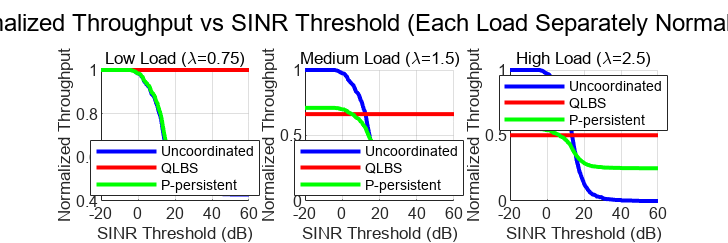



loadcell1 = cell(1, 3);
loadcell2 = cell(1, 3);
delaycell1 = cell(1, 3);
delaycell2 = cell(1, 3);

for loadIdx = 1:length(lambda)
    arrivalRate = lambda(loadIdx);

    % P-persistent 
    if(loadIdx == 1)
        p_persistent = 0.9;
    elseif(loadIdx == 2)
        p_persistent = 0.55;
    else
        p_persistent = 0.55;
    end


    queueBS1 = poissrnd(arrivalRate, 1, numSlots);
    queueBS2 = poissrnd(arrivalRate, 1, numSlots);

    transmitBS1 = zeros(1, numSlots);
    transmitBS2 = zeros(1, numSlots);
    transmitstatusBS1 = zeros(3, numSlots);
    transmitstatusBS2 = zeros(3, numSlots);

    delay1 = zeros(3, 1);
    delay2 = zeros(3, 1);

    for method = 1:3
        queue1 = cumsum(queueBS1);
        queue2 = cumsum(queueBS2);

        for t = 1:numSlots
            if method == 1 % Uncoordinated
                if queue1(t) >= maxdatarate && queue2(t) >= maxdatarate
                    transmitBS1(t) = maxdatarate;
                    transmitBS2(t) = maxdatarate;
                elseif queue1(t) >= maxdatarate
                    transmitBS1(t) = maxdatarate;
                    transmitBS2(t) = queue2(t);  
                elseif queue2(t) >= maxdatarate
                    transmitBS1(t) = queue1(t); 
                    transmitBS2(t) = maxdatarate;
                else
                    transmitBS1(t) = queue1(t);
                    transmitBS2(t) = queue2(t);  
                end

            elseif method == 2 % QLBS
                if queue1(t) > 0 && queue2(t) > 0
                    if queue1(t) > queue2(t) 
                        transmitBS1(t) = min(queue1(t), maxdatarate);
                        transmitBS2(t) = 0;
                    elseif queue1(t) < queue2(t)
                        transmitBS2(t) = min(queue2(t), maxdatarate);
                        transmitBS1(t) = 0;
                    else
                        if rand > 0.5
                            transmitBS1(t) = min(queue1(t), maxdatarate);
                            transmitBS2(t) = 0;
                        else
                            transmitBS2(t) = min(queue2(t), maxdatarate);
                            transmitBS1(t) = 0;
                        end
                    end
                else
                    if queue1(t) > 0 && queue2(t) == 0
                        transmitBS1(t) = min(queue1(t), maxdatarate);
                        transmitBS2(t) = 0;
                    elseif queue1(t) == 0 && queue2(t) > 0
                        transmitBS2(t) = min(queue2(t), maxdatarate);
                        transmitBS1(t) = 0;
                    else
                        transmitBS1(t) = 0;
                        transmitBS2(t) = 0;
                    end
                end

            elseif method == 3 % P-persistent
                if rand > p_persistent
                    transmitBS1(t) = 0; 
                else 
                    if queue1(t) > maxdatarate
                        transmitBS1(t) = maxdatarate;
                    else
                        transmitBS1(t) = queue1(t);
                    end
                end

                if rand > p_persistent
                    transmitBS2(t) = 0;
                else 
                    if queue2(t) > maxdatarate
                        transmitBS2(t) = maxdatarate;
                    else
                        transmitBS2(t) = queue2(t);
                    end
                end
            end 


            queue1(1,:) = queue1(1,:) - transmitBS1(t);
            queue2(1,:) = queue2(1,:) - transmitBS2(t);


            delay1(method,1) = delay1(method,1) + queue1(t);
            delay2(method,1) = delay2(method,1) + queue2(t);
        end

        transmitstatusBS1(method,:) = transmitBS1;
        transmitstatusBS2(method,:) = transmitBS2;
    end

    loadcell1{loadIdx} = transmitstatusBS1;
    loadcell2{loadIdx} = transmitstatusBS2;
    delaycell1{loadIdx} = delay1;
    delaycell2{loadIdx} = delay2;
end


% Calculate success rate for each threshold
for loadindex = 1:3
    for methodIndex = 1:3
        load1 = loadcell1{loadindex};
        loadrow1 = load1(methodIndex,:);
        for thresh_idx = 1:length(SINR_thresholds)
            throughput_vs_SINR(thresh_idx, methodIndex, loadindex) = ...
                success_rate_all_loads(thresh_idx, methodIndex, loadindex) * ...
                (sum(loadrow1))/numSlots * packet_size_bits / slot_duration;
        end
    end
end


figure('Position', [100, 100, 1200, 400]);
for load_idx = 1:3

    this_load_data = throughput_vs_SINR(:,:,load_idx); % [thresholds x methods]
    max_val_for_this_load = max(this_load_data(:));

    % 做归一化
    normalized_data = this_load_data / max_val_for_this_load;

    subplot(1, 3, load_idx);
    hold on;
    for method = 1:3
        plot(SINR_thresholds, normalized_data(:, method), ...
            '-', 'Color', colors{method}, 'LineWidth', 2, ...
            'MarkerFaceColor', colors{method});
    end
    grid on;
    xlabel('SINR Threshold (dB)');
    ylabel('Normalized Throughput');
    title(load_names{load_idx});
    legend(methods, 'Location', 'best');
    hold off;
end
sgtitle('Normalized Throughput vs SINR Threshold (Each Load Separately Normalized)', 'FontSize', 12);